% ==== Bounds ====
lb = [273, 273];    % [T0, Tj] lower
ub = [373, 373];    % [T0, Tj] upper


% ==== Initial guess for decision variables ====
T0 = 373;   % K
Tj = 343;   % K
params_init = [T0, Tj];


% ==== Objective: maximize CA(tf) -> minimize -CA(tf) ====
objFun = @(params) objectFunction(params);

% ==== Optimize ====
opts = optimoptions('fmincon', 'Display', 'iter', 'MaxIterations', 10000);
[paramsFinal, fval, exitflag, output] = fmincon(objFun, params_init, [], [], [], [], lb, ub, [], opts);

Your initial point x0 is not between bounds lb and ub; FMINCON
shifted x0 to strictly satisfy the bounds.

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       3   -5.169267e+00    0.000e+00    3.872e-02
    1       6   -5.171546e+00    0.000e+00    3.608e-02    4.668e-02
    2       9   -5.183558e+00    0.000e+00    3.580e-02    2.472e-01
    3      12   -5.241177e+00    0.000e+00    3.428e-02    1.213e+00
    4      15   -5.478842e+00    0.000e+00    2.505e-02    5.829e+00
    5      18   -6.195069e+00    0.000e+00    4.842e-02    1.739e+01
    6      24   -6.253538e+00    0.000e+00    3.483e-02    1.077e+01
    7      27   -6.404975e+00    0.000e+00    1.224e-02    4.366e+00
    8      31   -6.412603e+00    0.000e+00    2.577e-03    1.185e+00
    9      34   -6.412905e+00    0.000e+00    1.866e-04    2.057e-01
   10      37   -6.412907e+00    0.000e+00    8.209e-06    1.566e-02
   11    

disp('Optimal [T0, Tj] = '), disp(paramsFinal)

Optimal [T0, Tj] = 
  348.5881  324.0489



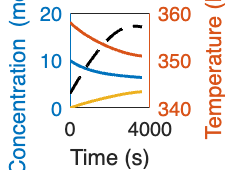

[X, Y] = solveEquationSystem(paramsFinal);


figure;

yyaxis left
plot(X, Y(:,1), '-', 'LineWidth', 1.5, 'Color', [0 0.4470 0.7410]); % 蓝色
hold on;
plot(X, Y(:,2), '-', 'LineWidth', 1.5, 'Color', [0.8500 0.3250 0.0980]); % 红橙色
plot(X, Y(:,3), '-', 'LineWidth', 1.5, 'Color', [0.9290 0.6940 0.1250]); % 黄色
xlabel('Time (s)');
ylabel('Concentration (mol/m^3)');

yyaxis right
plot(X, Y(:,4), 'k--', 'LineWidth', 1.5);
ylabel('Temperature (K)');


title([vars{k} ' vs Time for different scenarios']);

Undefined variable 'vars'.

legend({'C_A', 'C_B', 'C_C', 'T'}, 'Location', 'best');
grid on;
